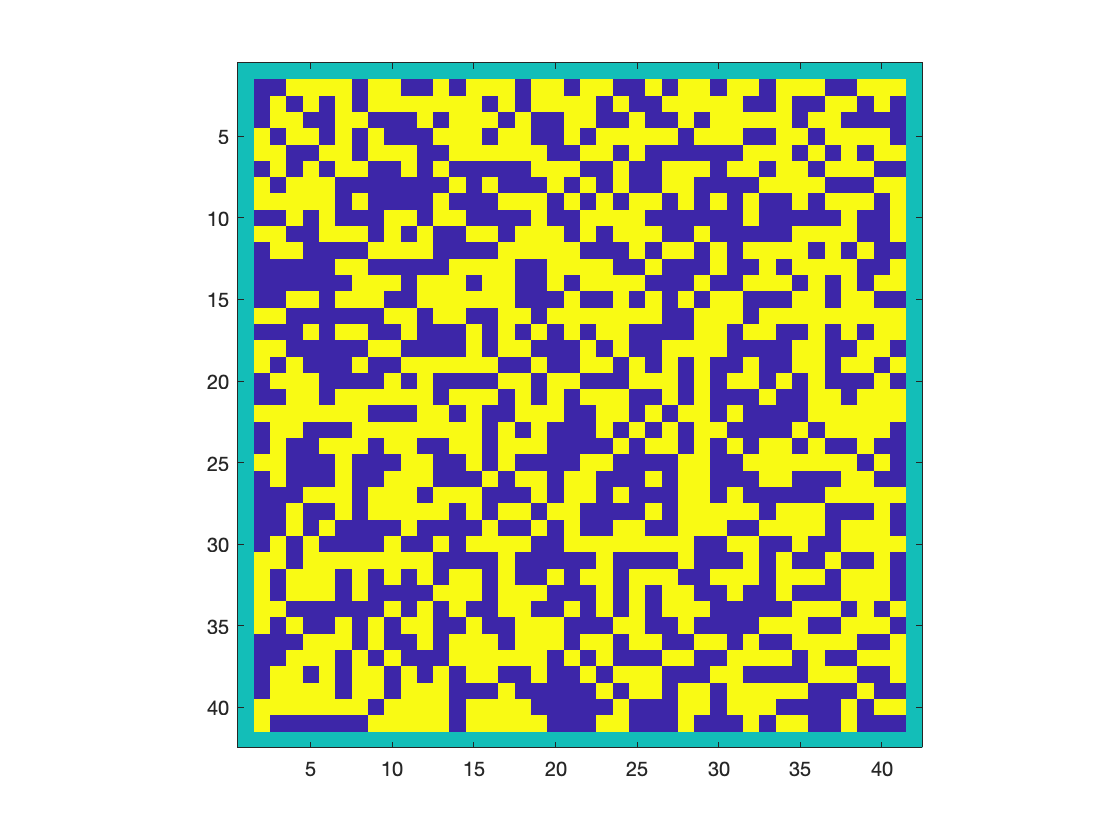

clear

N = 42;

J = 1; %eV

k_b = 8.617333262*10^-5;%eV/K

T = [1500:125:50000];

beta = 1./(k_b.*T);

%beta = [7.75:-0.01:2.2];

T_c = 2.27;

steps = 1000;

[spins, ~] = initializeLattice(N, 0, 0, 0);

figure;
imagesc(spins)
axis square

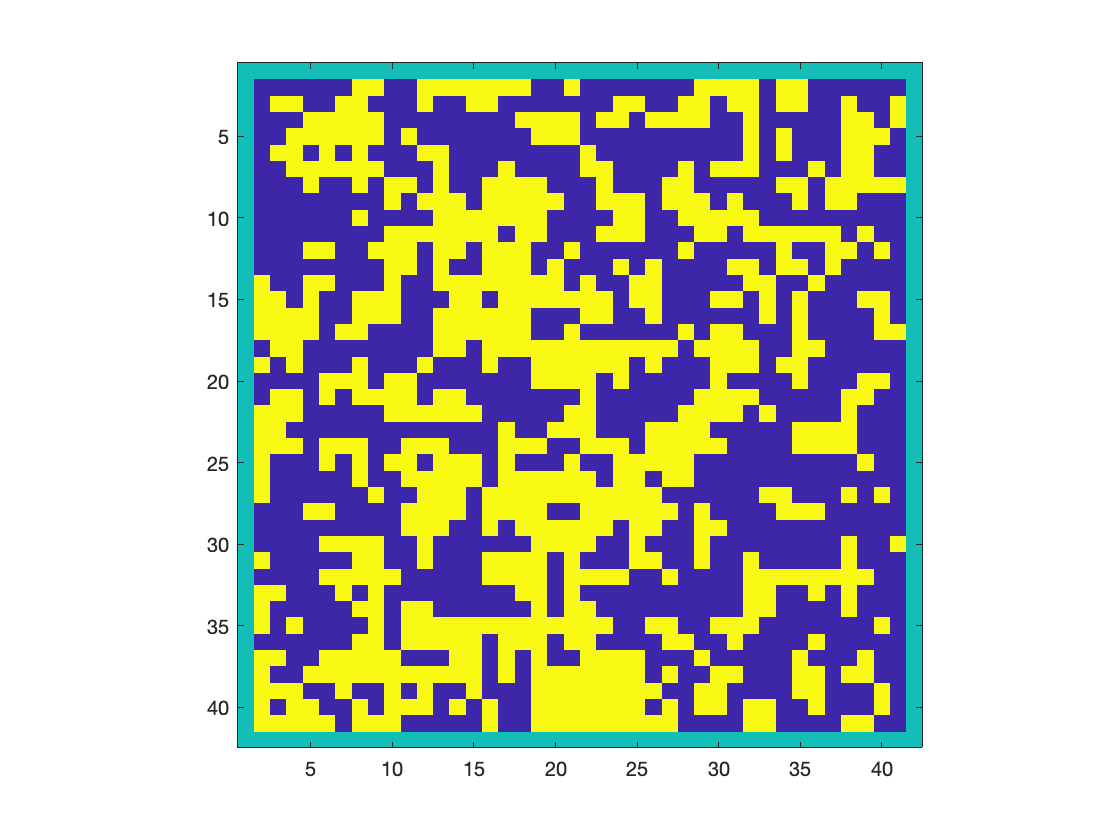

tic
for n = 1:length(beta)
    
    for t = 1:steps
        
        for x = 2:N-1
            for y = 2:N-1
                
                delta_spin = -1*spins(x,y) - spins(x,y);
                
                Snn = spins(x+1, y) + ...
                    spins(x-1, y) + ...
                    spins(x, y+1) + ...
                    spins(x, y-1);
                
                spins(x, y) = -1*spins(x,y);
                
                dE = delta_spin*(-1*J*Snn);
                
                p = exp(-1*dE*beta(n));
                r = rand;
                
                if dE < 0 || p >= r
                    continue
                else
                    spins(x,y) = -1*spins(x,y);
                end
                
            end
        end
        
        nHS_temp(n, t) = n_HSfrac(spins);
        M_temp(n, t) = abs(sum(spins, 'all'))/((N-2)^2);
        
    end
    nHS(n) = mean(nHS_temp(n, :));
    M(n) = mean(M_temp(n, :));
    %toc
end
% At the end of each step
imagesc(spins)
axis square

toc

Elapsed time is 37.405106 seconds.


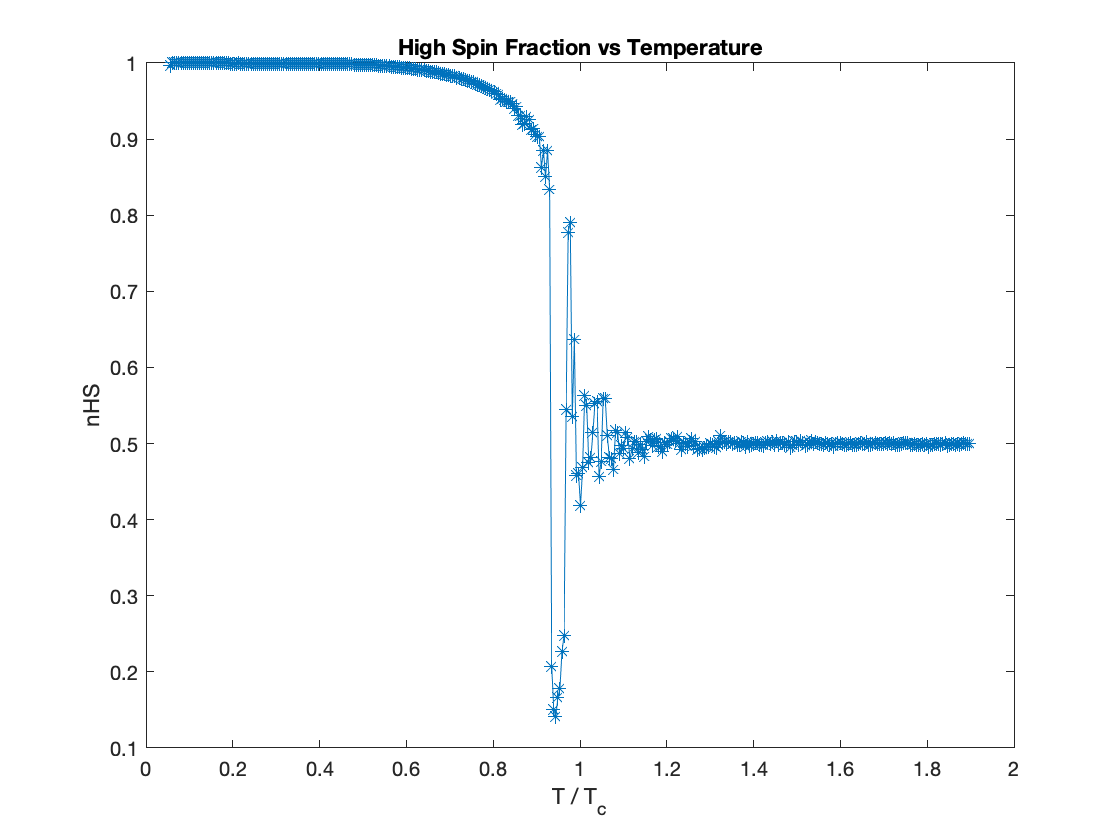


figure;
plot(1./(T_c.*beta), nHS, '*-')
title("High Spin Fraction vs Temperature")
xlabel("T / T_c", "Interpreter","tex")
ylabel("nHS")

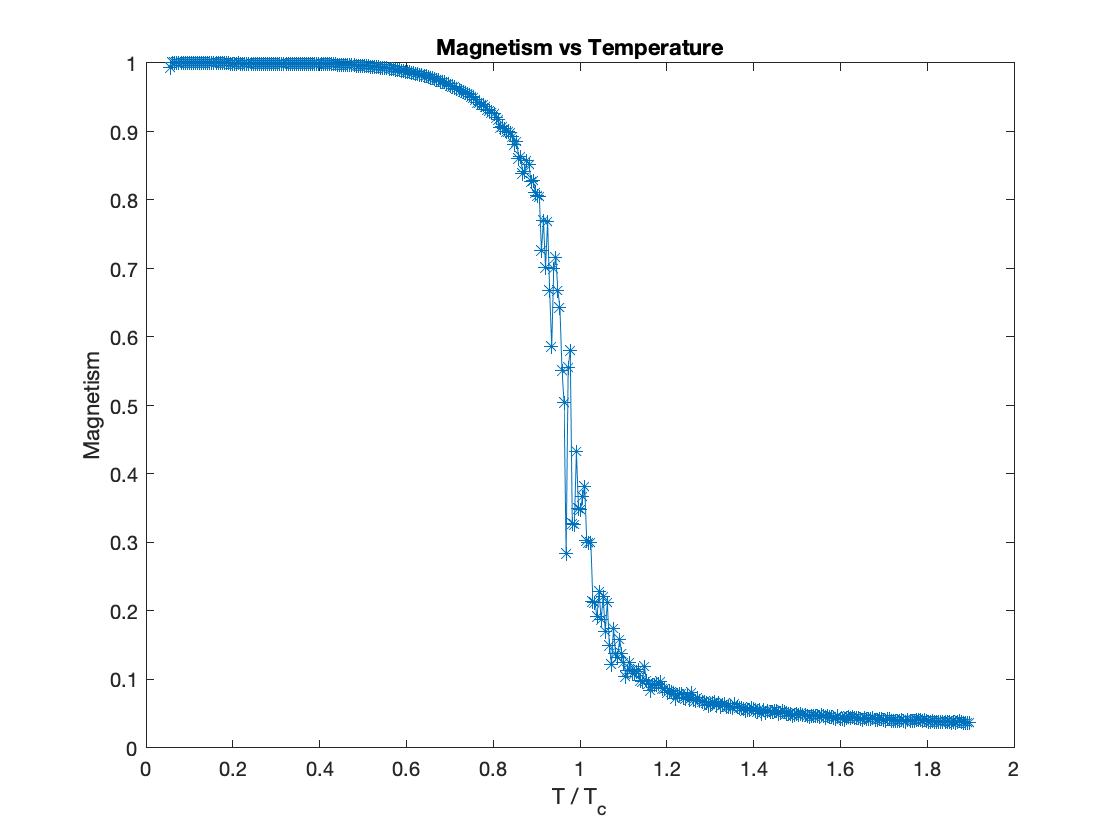

figure;
plot(1./(T_c.*beta), M, '*-')
title("Magnetism vs Temperature")
xlabel("T / T_c", "Interpreter","tex")
ylabel("Magnetism")

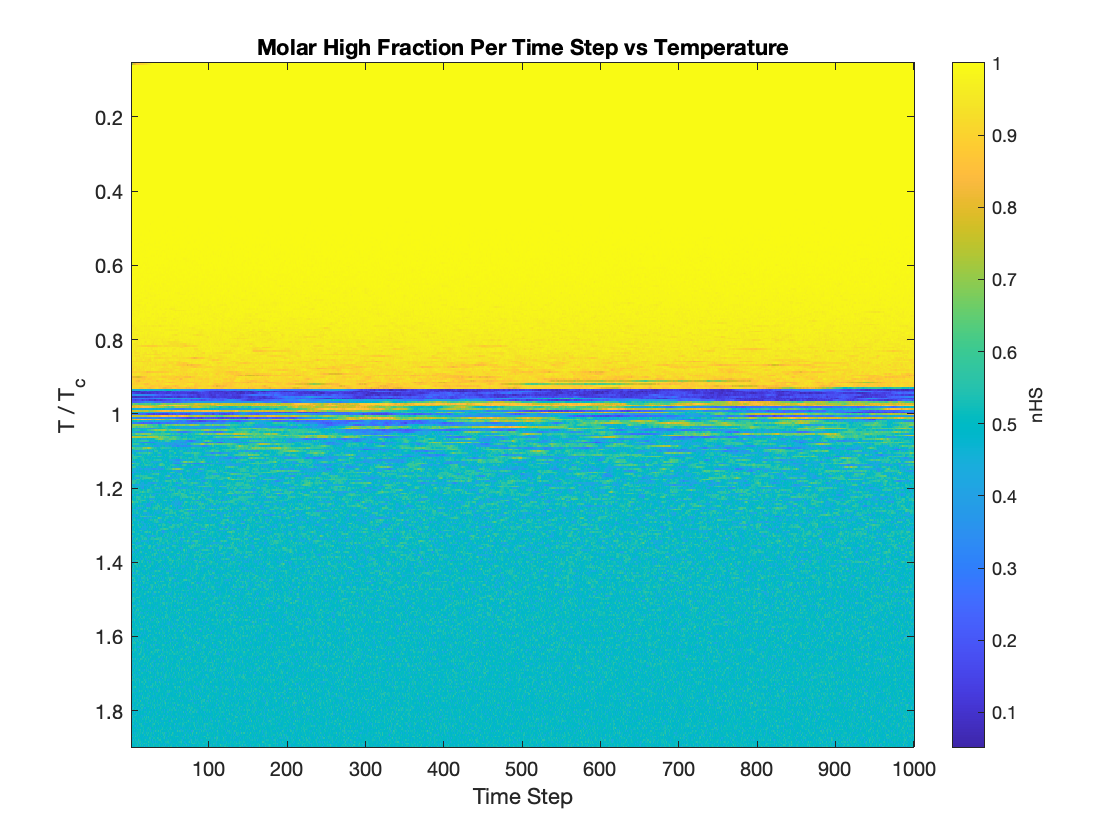

figure;
imagesc([1:steps], 1./(T_c.*beta), nHS_temp)
xlabel("Time Step")
ylabel("T / T_c", "Interpreter","tex")
title("Molar High Fraction Per Time Step vs Temperature")
c = colorbar;
c.Label.String = 'nHS';

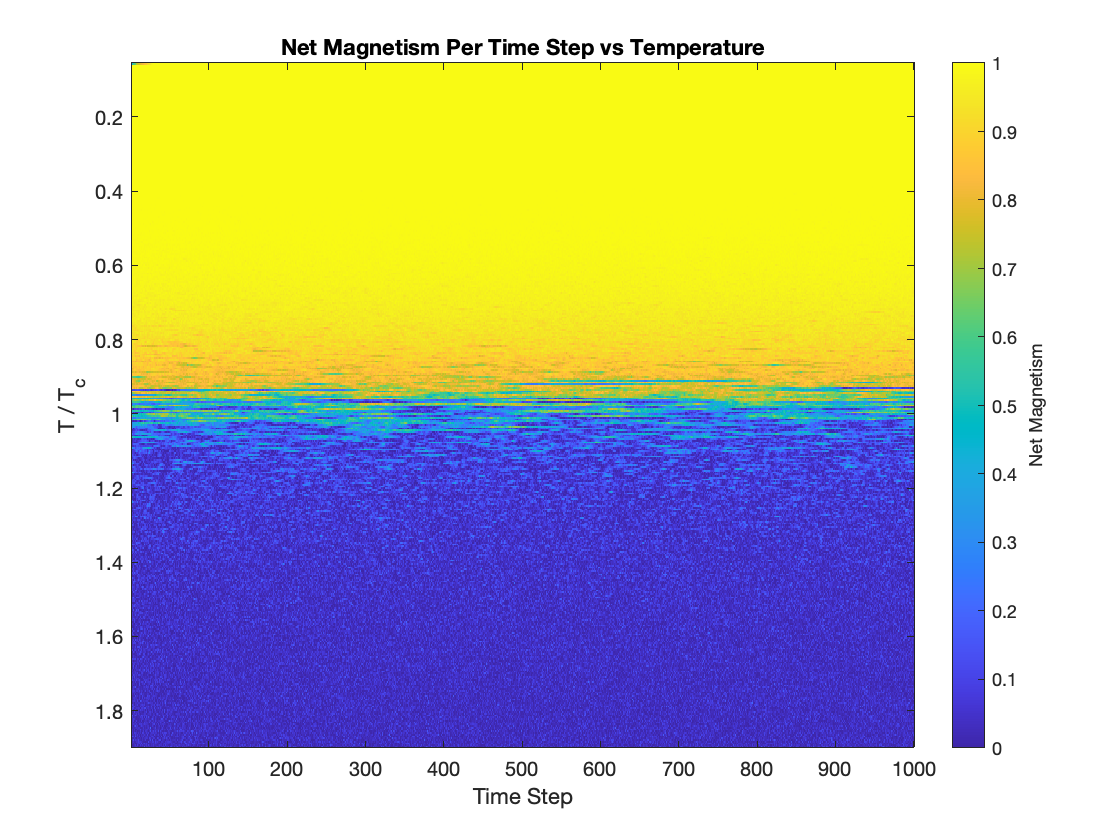

figure;
imagesc([1:steps], 1./(T_c.*beta), M_temp)
xlabel("Time Step")
ylabel("T / T_c", "Interpreter","tex")
title("Net Magnetism Per Time Step vs Temperature")
c = colorbar;
c.Label.String = 'Net Magnetism';